# **Script: **

This script was utilized for report the results of the conference article: *"Visualization of in-vitro Blood Vessels in Contrast Images Based on Discrete Wavelet Transform Decomposition"*

clc; clear; close all;

Parameters: size of the isometric window, wavelet function used and level of decomposition

type_window = 5;
type_wavelet = 'db5';
type_level = 3;

Read raw speckle image from .tif file

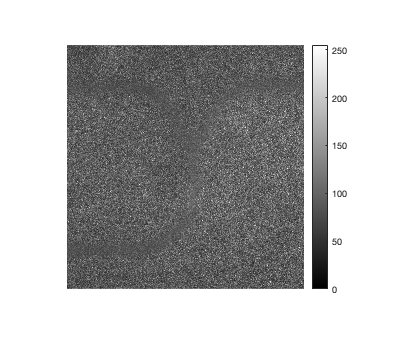

im_raw = imread('im_bf.tif',1);
imshow(im_raw); colormap gray; colorbar

Computing spatial contrast and normalization values beetwen [0,1]

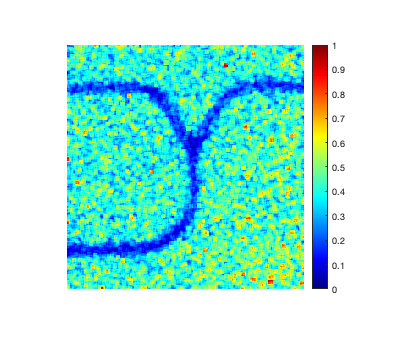

im_contrast = f_sk(im_raw,type_window);
im_contrast = mat2gray(im_contrast); 
imshow(im_contrast); colormap jet; colorbar

Denoising 

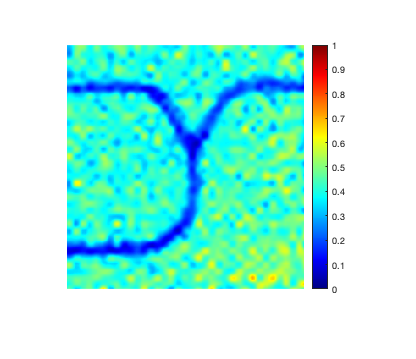

im_synth = f_denoising(im_contrast,type_wavelet,type_level);
imshow(im_synth); colormap jet; colorbar

Binarize 

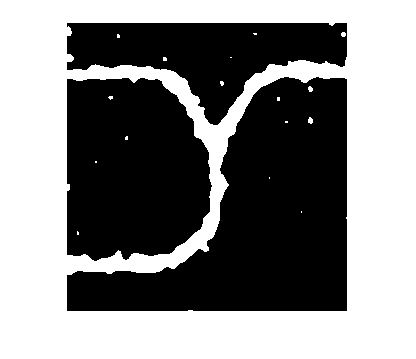

[im_thresh,im_binary] = f_binarize(im_synth,im_contrast);
imshow(im_thresh); colormap bone

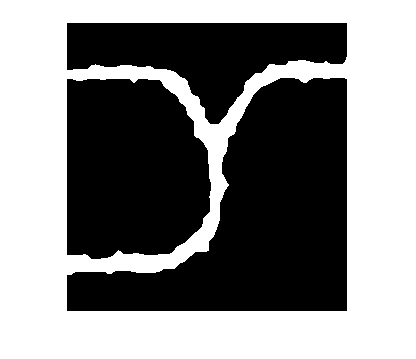

imshow(im_binary); colormap bone

Maping 

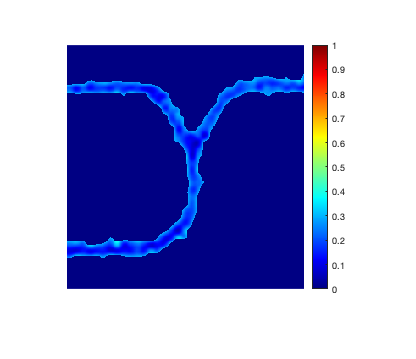

map_synth = f_mapping(im_synth,im_binary);

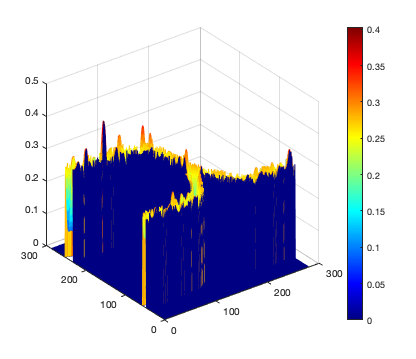

mesh(map_synth); colormap jet; colorbar; 

# **Main function: **

function i2mtc2019(im_raw)

type_window = 5;
type_wavelet = 'db5';
type_level = 3;

im_contrast = f_sk(im_raw,type_window);
im_contrast = mat2gray(im_contrast); 
im_synth = f_denoising(im_contrast,type_wavelet,type_level);
[im_thresh,im_binary] = f_binarize(im_synth,im_contrast);
map_synth = f_mapping(im_synth,im_binary);

end

# **Auxiliar functions: **

function map_synth = f_mapping(im_synth,im_binary)

[rows,cols] = size(im_binary);
map_synth = zeros(rows,cols);

for i = 1:1:rows
    for j = 1:1:cols      
        if im_binary(i,j) == 1
            map_synth(i,j) = im_synth(i,j);
        end
    end
end

end


function [im_thresh,im_binary] = f_binarize(im_synth,im_contrast)

[val_thresh, val_nabla] = multithresh(im_synth,2);
im_quantize = imquantize(im_synth,val_thresh);
im_rgb = label2rgb(im_quantize);
im_color = im_rgb(:,:,2);
im_thresh = im_color>=1;
im_thresh = not(im_thresh);

val_elements = regionprops('table',im_thresh,'Area');
val_object = bwareaopen(im_thresh,max(val_elements.Area));
val_se = strel('disk', 7); 
im_binary = imclose(val_object,val_se); 

[rows,cols] = size(im_contrast);
im_output = zeros(rows,cols);

for i = 1:1:rows
    for j = 1:1:cols
        if im_binary(i,j) == 1
            im_output(i,j) = 1;
        end
    end
end

im_binary = im_output;

end


function im_contrast = f_sk(im_input,type_window)

d = (type_window-1)/2;

mat_header = im_input(1:d,:);
mat_footer = im_input(end+1-d:end,:);
mat_inside = [mat_header;im_input;mat_footer];
mat_left = mat_inside(:,1:d);
mat_right = mat_inside(:,end-d+1:end);
im_raw = [mat_left, mat_inside, mat_right];

[rows,cols]=size(im_raw);
im_contrast = zeros(rows,cols);

for i=1+d:1:rows-d
    for j=1+d:1:cols-d

        val_window = im_raw(i-d:i+d,j-d:j+d);
        val_mean = mean2(val_window);
        val_std = std2(val_window);
        val_contrast = val_std/val_mean;
        im_contrast(i,j) = val_contrast;
        
    end
end

im_contrast = im_contrast(d+1:end-d,d+1:end-d);

end


function im_synth = f_denoising(im_contrast,type_wavelet,type_level)

[C,S] = wavedec2(im_contrast,type_level,type_wavelet);
A = appcoef2(C,S,type_wavelet);

switch type_level
    case 1
        R = idwt2(A,[],[],[],type_wavelet);
        
    case 2
        R1 = idwt2(A,[],[],[],type_wavelet);
        R = idwt2(R1,[],[],[],type_wavelet);
        
    case 3
        R1 = idwt2(A,[],[],[],type_wavelet);
        R2 = idwt2(R1,[],[],[],type_wavelet);
        R = idwt2(R2,[],[],[],type_wavelet);
        
    case 4
        R1 = idwt2(A,[],[],[],type_wavelet);
        R2 = idwt2(R1,[],[],[],type_wavelet);
        R3 = idwt2(R2,[],[],[],type_wavelet);
        R = idwt2(R3,[],[],[],type_wavelet);
        
    case 5
        R1 = idwt2(A,[],[],[],type_wavelet);
        R2 = idwt2(R1,[],[],[],type_wavelet);
        R3 = idwt2(R2,[],[],[],type_wavelet);
        R4 = idwt2(R3,[],[],[],type_wavelet);
        R = idwt2(R4,[],[],[],type_wavelet);
        
    case 6
        R1 = idwt2(A,[],[],[],type_wavelet);
        R2 = idwt2(R1,[],[],[],type_wavelet);
        R3 = idwt2(R2,[],[],[],type_wavelet);
        R4 = idwt2(R3,[],[],[],type_wavelet);
        R5 = idwt2(R4,[],[],[],type_wavelet);
        R = idwt2(R5,[],[],[],type_wavelet);
        
    otherwise
        disp('Error')
end

im_synth = R;

end

